# Ising Model 2D

## Import data 1

path="../../../cmake-build-release/bin/IsingResults.tsv";
%path="./IsingResults2.tsv";
%path="./IsingResults_from_headless_system.tsv";

numOfTemps=readmatrix(path,"FileType","text","Delimiter","\t","Range",'B1:B1')

numOfTemps = 16

numOfIterations=readmatrix(path,"FileType","text","Delimiter","\t","Range",'B2:B2')

numOfIterations = 100

it=numOfTemps*numOfIterations;

[N1, temp1, mag1, en1, ~, ~] = importfile(path,1,it);
[N2, temp2, mag2, en2, ~, ~] = importfile(path,it+1,2*it);
[N3, temp3, mag3, en3, ~, ~] = importfile(path,2*it+1,3*it);
[N4, temp4, mag4, en4, ~, ~] = importfile(path,3*it+1,4*it);
[N5, temp5, mag5, en5, ~, ~] = importfile(path,4*it+1,5*it);

## Import data 2

%path="../../../cmake-build-release/bin/IsingResults.tsv";
path="./IsingResults2.tsv";
%path="./IsingResults_from_headless_system.tsv";


%[temp1, en1,mag1] = importfileAppend(path,temp1,en1,mag1);
%[temp2, en2,mag2] = importfileAppend(path,temp2,en2,mag2);
%[temp3, en3,mag3] = importfileAppend(path,temp3,en3,mag3);
%[temp4, en4,mag4] = importfileAppend(path,temp4,en4,mag4);
%[temp5, en5,mag5] = importfileAppend(path,temp5,en5,mag5);

## Energy: Reduce data to mean and std

reduce data now

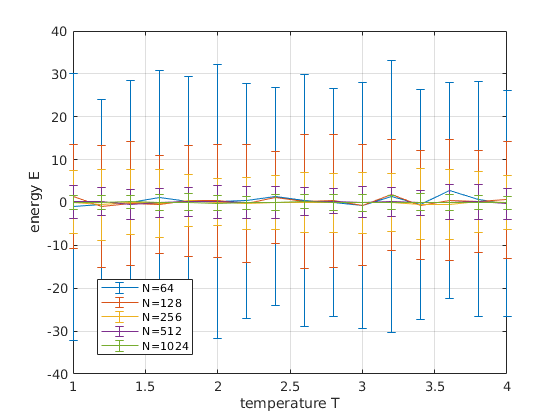

[en1_mean,en1_std,en1_var,en1_weight,en1_corr] = ReduceObservable(en1,temp1);
[en2_mean,en2_std,en2_var,en2_weight,en2_corr] = ReduceObservable(en2,temp2);
[en3_mean,en3_std,en3_var,en3_weight,en3_corr] = ReduceObservable(en3,temp3);
[en4_mean,en4_std,en4_var,en4_weight,en4_corr] = ReduceObservable(en4,temp4);
[en5_mean,en5_std,en5_var,en5_weight,en5_corr] = ReduceObservable(en5,temp5);
temp_red=unique(temp1);

figure(1)
clf
errorbar(temp_red,en1_mean,2*en1_std,"DisplayName","N="+N1)
hold on
errorbar(temp_red,en2_mean,2*en2_std,"DisplayName","N="+N2)
errorbar(temp_red,en3_mean,2*en3_std,"DisplayName","N="+N3)
errorbar(temp_red,en4_mean,2*en4_std,"DisplayName","N="+N4)
errorbar(temp_red,en5_mean,2*en5_std,"DisplayName","N="+N5)
grid on
xlabel("temperature T")
ylabel("energy E")
legend("Location","best")

## Auto-Correlation-length energy

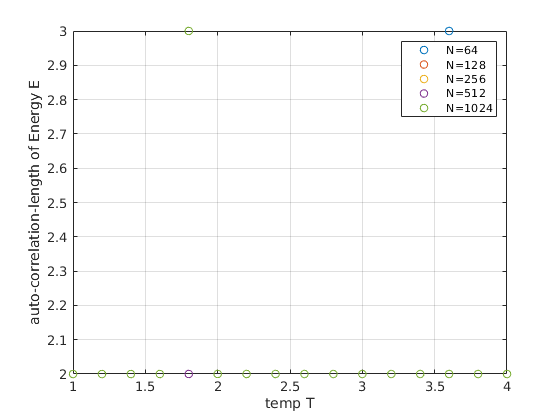

figure(1)
clf
scatter(temp_red,en1_corr,"DisplayName","N="+N1);
hold on
scatter(temp_red,en2_corr,"DisplayName","N="+N2);
scatter(temp_red,en3_corr,"DisplayName","N="+N3);
scatter(temp_red,en4_corr,"DisplayName","N="+N4);
scatter(temp_red,en5_corr,"DisplayName","N="+N5);
box on
grid on
ylabel("auto-correlation-length of Energy E")
xlabel("temp T")
legend()

## Absolute Magnetization: Reduce data to mean and std

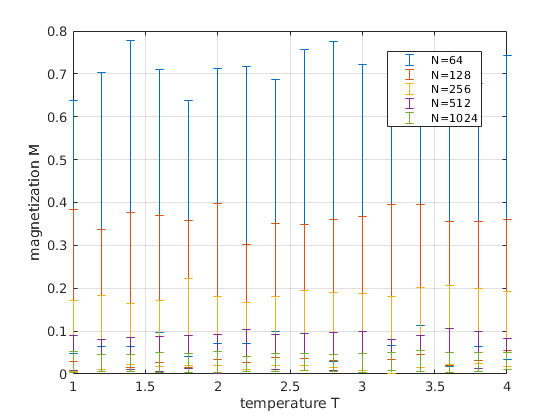

[mag1_mean_abs,mag1_std,mag1_var,mag1_weight,mag1_corr] = ReduceObservable(abs(mag1),temp1);
[mag2_mean_abs,mag2_std,mag2_var,mag2_weight,mag2_corr] = ReduceObservable(abs(mag2),temp1);
[mag3_mean_abs,mag3_std,mag3_var,mag3_weight,mag3_corr] = ReduceObservable(abs(mag3),temp1);
[mag4_mean_abs,mag4_std,mag4_var,mag4_weight,mag4_corr] = ReduceObservable(abs(mag4),temp1);
[mag5_mean_abs,mag5_std,mag5_var,mag5_weight,mag5_corr] = ReduceObservable(abs(mag5),temp1);

figure(1)
clf
errorbar(temp_red,mag1_mean_abs,mag1_std,"DisplayName","N="+N1,"LineStyle","none")
hold on
errorbar(temp_red,mag2_mean_abs,mag2_std,"DisplayName","N="+N2,"LineStyle","none")
errorbar(temp_red,mag3_mean_abs,mag3_std,"DisplayName","N="+N3,"LineStyle","none")
errorbar(temp_red,mag4_mean_abs,mag4_std,"DisplayName","N="+N4,"LineStyle","none")
errorbar(temp_red,mag5_mean_abs,mag5_std,"DisplayName","N="+N5,"LineStyle","none")
grid on
xlabel("temperature T")
ylabel("magnetization M")
legend("Location","best")

## Auto-Correlation-length magnetization

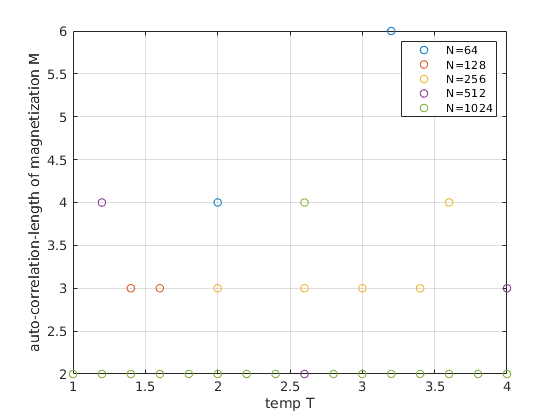

figure(1)
clf
scatter(temp_red,mag1_corr,"DisplayName","N="+N1);
hold on
scatter(temp_red,mag2_corr,"DisplayName","N="+N2);
scatter(temp_red,mag3_corr,"DisplayName","N="+N3);
scatter(temp_red,mag4_corr,"DisplayName","N="+N4);
scatter(temp_red,mag5_corr,"DisplayName","N="+N5);
box on
grid on
ylabel("auto-correlation-length of magnetization M")
xlabel("temp T")
legend()

## heatCapacity

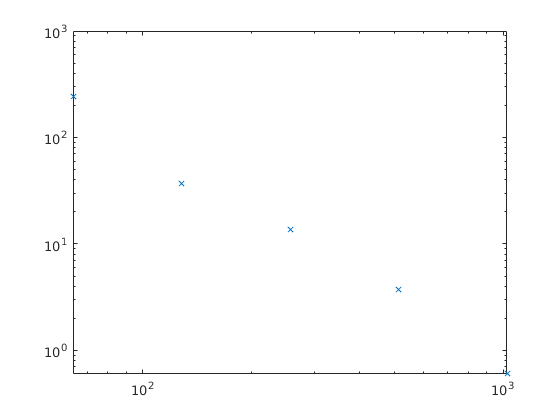

heatC1=en1_var./temp_red.^2;
heatC2=en2_var./temp_red.^2;
heatC3=en3_var./temp_red.^2;
heatC4=en4_var./temp_red.^2;
heatC5=en5_var./temp_red.^2;
figure(4)
clf
loglog([N1,N2,N3,N4,N5],[max(heatC1),max(heatC2),max(heatC3),max(heatC4),max(heatC5)],'x')

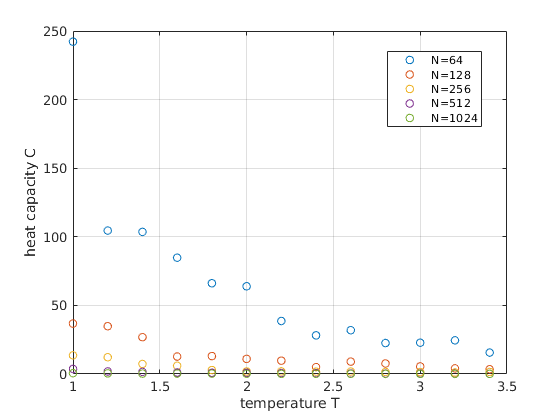


figure(4)
clf
scatter(temp_red,heatC1,"DisplayName","N="+N1)
hold on
scatter(temp_red,heatC2,"DisplayName","N="+N2)
scatter(temp_red,heatC3,"DisplayName","N="+N3)
scatter(temp_red,heatC4,"DisplayName","N="+N4)
scatter(temp_red,heatC5,"DisplayName","N="+N5)
grid on
box on
xlim([1,3.5])
xlabel("temperature T")
ylabel("heat capacity C")
legend("Location","best")

## Susceptibility

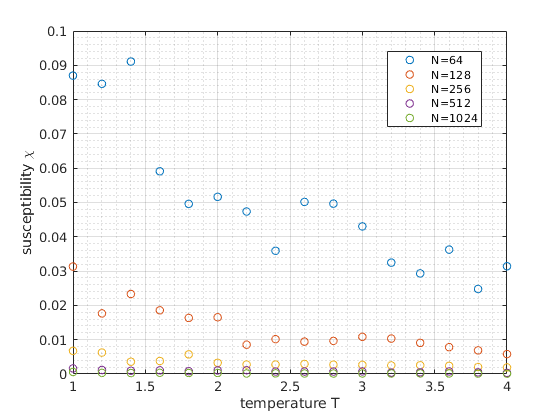

chi1=mag1_var./temp_red;
chi2=mag2_var./temp_red;
chi3=mag3_var./temp_red;
chi4=mag4_var./temp_red;
chi5=mag5_var./temp_red;

figure(5)
clf
scatter(temp_red,chi1,"DisplayName","N="+N1)
hold on
scatter(temp_red,chi2,"DisplayName","N="+N2)
scatter(temp_red,chi3,"DisplayName","N="+N3)
scatter(temp_red,chi4,"DisplayName","N="+N4)
scatter(temp_red,chi5,"DisplayName","N="+N5)
grid on
grid minor
box on
%xlim([1.5,3.5])
xlabel("temperature T")
ylabel("susceptibility \chi")
legend("Location","best")

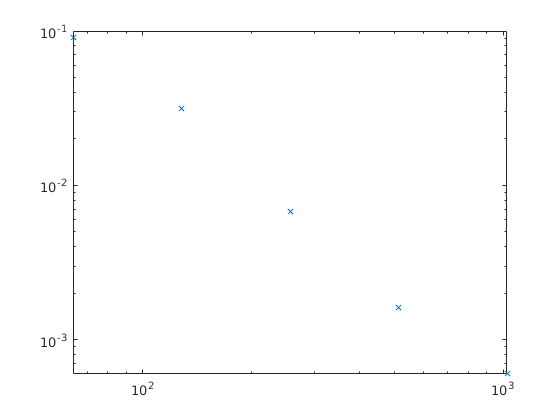

figure(5)
clf
loglog([N1,N2,N3,N4,N5],[max(chi1),max(chi2),max(chi3),max(chi4),max(chi5)],'x')